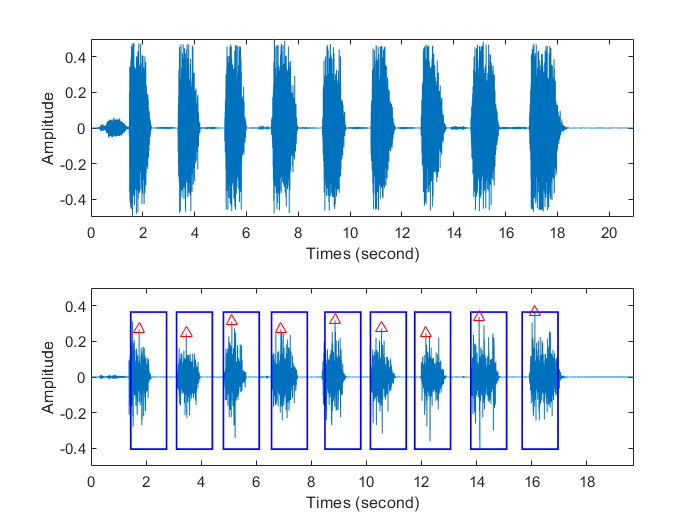

clear all

file=['C:\Users\Desktop\25.wav'];

[data, fs] = audioread(file);

%if consisiting 4 channels, 
%dada=data(:,1); %use this line of code to pick 1 channel for processing
%if only 1 channel for demo, just ignore this line of code

duration = length(data) / fs;
t = linspace(0, duration, length(data));

threshold=0.8;

outlier=data;
outlier(abs(outlier) > threshold)=0;

wpt=wpdec(outlier,5,'sym8');
x = wprcoef(wpt,[5 0]);

[modified_y,ttt,f1]=spec(x,fs);

t = (0:length(x)-1) / fs;
t_modified = (0:length(modified_y)-1) / fs;

X=real(modified_y);

px=X;
px(find(abs(px)<5e-07))=0;

px=px*625;

subplot(2,1,1)
plot(t,data)
xlim([0, duration])
ylim([min(data),max(data)])
xlabel('Times (second)')
ylabel('Amplitude')

subplot(2,1,2)
plot(t_modified,px)
xlim([0 max(t_modified)])
xlabel('Times (second)')
ylabel('Amplitude')
hold on

ttt=hours(1:1:(size(px)));
TFS = islocalmax(px,'MinSeparation',hours(62000),'SamplePoints',ttt);
local=find(TFS==1);
size(local);


%need to change a local path
sPath='C:\Users\Desktop\';

period=1.3;
c=1;
extSig={};
localNew=[];
box=max(px);
box1=min(px);

for i =1:length(local)

    tmp=local(i);
    
    sss=where(px,tmp);

    if abs(px(tmp))>5e-06*625

        t_f=t_modified(sss);
        t_d=t_f+period;

        if (t_f+period)>max(t_modified)

            disp("*")
            break
        else
            %             disp(c)
            localNew(c)=local(i);


            extra=px(sss:(sss+1.3*48e3));
            
            rectangle('Position', [t_f-0.3, box1, period,box+abs(box1)], 'EdgeColor', 'b', 'LineWidth', 1);
            hold on

%             %save the breathing period into mat file for further detection
%             
            coeffs=mfcc(extra,fs);

            %s4-channel1-period c-label 0
            rename=[sPath,num2str(25),'_',num2str(1),'_',num2str(c),'_',num2str(0),'.mat'];
            save(rename,"coeffs")
            c=c+1;

        end
    end
end

plot(t_modified(localNew),px(localNew),'r^')

ylim([min(data),max(data)])

hold off


disp('The number of breathing cycle is ')

The number of breathing cycle is 


disp(c-1)

     9



function sss=where(ens,tmp)

sss=0;
candidates = [];
count=1;
for i = tmp:-1:1
    if ens(i) ==0
        candidates(count)=i;
        count=count+1;
    end

end

continuous_count = 0;


for i = 1:length(candidates)-7 
   
    if all(diff(candidates(i:i+7)) == -1)
        sss=candidates(i);
        
        continuous_count = 8;
        break;
    end
end

end


function [ix,ti,f1]=spec(x,fs)

nfft = 1024;
hop_size = 256;
[S1, f1, t1] = spectrogram(x, flattopwin(nfft), nfft - hop_size, nfft, fs);

threshold_duration = 3;
threshold_samples = threshold_duration * fs; 


noise_power = mean(abs(x(1:threshold_samples)).^2); 


alpha = 3;
modified_power = max(abs(S1).^2 - alpha * noise_power, 0);


modified_S = sqrt(modified_power) .* exp(1i * angle(S1));

[ix,ti] = istft(S1,fs,'Window',hamming(256,'periodic'),'OverlapLength',15);
end